# Software Defined Radio

Implementatio of a software defined radio receiver.

**Based on **

[softwarere receiver design  by C. Richard Johnson, Jr, William A.

Sethares, Andrew G. Klein]

**By**

Abanoub Methany 

Anas Abdulhalim

**supervesion**

Prof./ Volker Strümpen

## Code workflow

The work flow of the code and different processing stages of the signal 

goes as follows:

1. choose signal 

2. load sginal >> r

3. specify receiver parameters

4. anti image BPF >> x_if

5. carrier estimate and demodulation >> x_BB

6. clock recovery and interpolator >> x_down

7. matched filtering and header/ frames extractionn >> x_message, header

8. Equilizer filter :

    header ----> LMS equilizer 

    x_message -----> DD equilzer 

9. combined equilizer filter >> x_message_equ

10. decision device (quantizer) >> mprime

11.pam2letter decoder >> reconstructed_message 

## Block Diagram

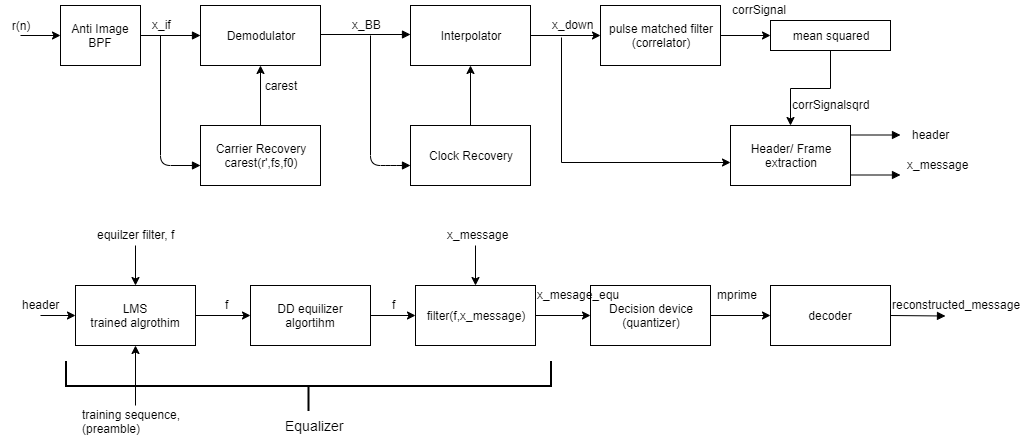

## Implementation

#### **1. Choose Signal **

msg =input(['to choose message\n' ...
'mysteryA enter 1\n' ...
'mysteryB enter 2\n' ...
'mysteryC enter 3\n' ...
':: ']);

#### **2. load signal and set its specs**

%variable messageName is defined for each message to save results later on
if msg ==1
    load("mysteryA.mat"); 
    messageName= 'mysteryA';
    srrc_length= 8;
    beta= 0.1;
    t_T= 8e-6 ;
    f_if= 1.7e6;
    fs= 800e3 ;
    

elseif msg == 2
    load("mysteryB.mat");
    messageName= 'mysteryB';
    srrc_length= 4;
    beta= 0.3;
    t_T= 10.2e-6 ;
    f_if= 1.95e6;
    fs= 700e3;
    
elseif msg==3
    load("mysteryC.mat"); 
    messageName= 'mysteryC';
    srrc_length= 3;
    beta= 0.5;
    t_T= 8.3e-6 ;
    f_if= 2.45e6;
    fs= 750e3;
else
    return;
end

#### **3. receiver parameters**

preamble='A0Oh well whatever Nevermind';
M =fs*t_T;                                   % upsampling ratio 
f0 = f_if;
N= length(r);

signal was sampled by a sub-Nyquist frequency

iterate to find the signal image with lowest f0 (closet to base band)

while abs(f0-fs) < f0                     
    f0=abs(f0-fs);
end

#### **4. Anti Image BPF**

•To remove channel image interferers and signal unwanted copies we apply a BPF around f0 with BW a little greater than singal BW.

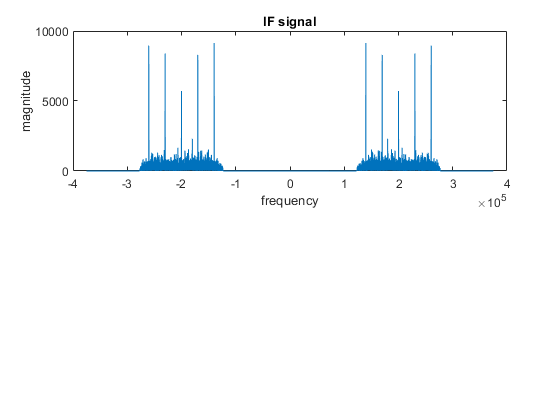

omegaC =2*f0/fs;
f1= omegaC-0.21;
f2= omegaC-0.2;
f3= omegaC+0.2;
f4= omegaC+0.21;

fl=500; ff=[0 f1 f2 f3 f4 1];       % BPF center frequency at .4
fa=[0 0 1 1 0 0];                   % which is twice f_0
h=firpm(fl,ff,fa);                  % BPF design via firpm
x_if=filtfilt(h,1,r);                  % filter to give preprocessed r

figure(1)
subplot(2,1,1), plotspec(x_if,1/fs);
title('IF signal');

#### **5. Carrier estimate and demodulation**

5.1. Carrier estimate

 Carest function uses a dual-PLL to recover carrier from received signal.

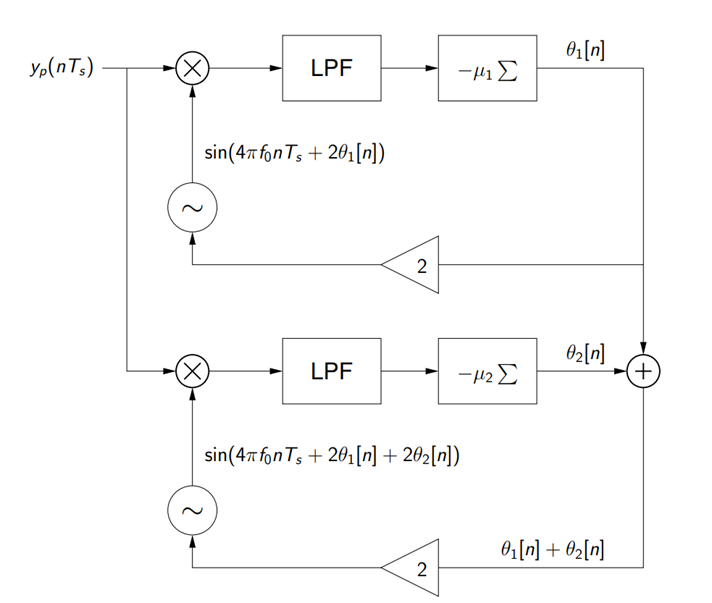

 Before passing passing it through the PLL it need some pre-processing, namely squaring then passing it to a BPF.

When squaring the signal its bandwidth/ center frequency doubles and hence if fs<2*(2*f0), the squared signal will be distorted.

 For this reason, under that condition, the signal is upsampled by a factor of 2.

5.2.Demodulation

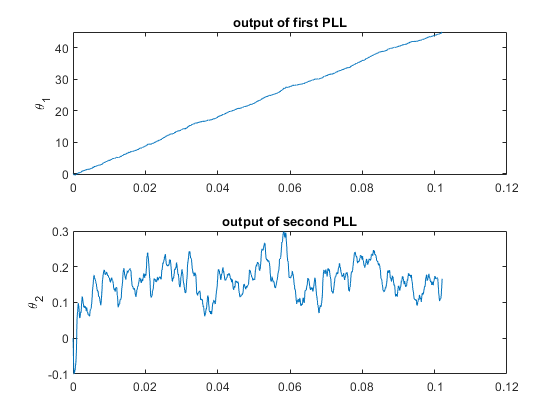

x_BB=x_if.*carest(r',f0,fs)'; 

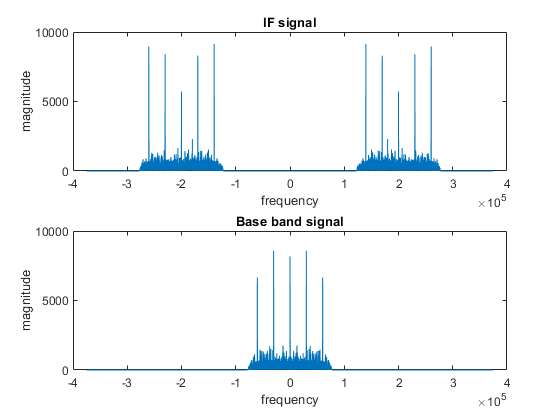


fl=500; ff=[0 .25 .26 1]; fa=[1 1 0 0];                  
h=firpm(fl,ff,fa);                                                                                                   
x_BB=filtfilt(h,1,x_BB);                 %Base band signal                                  

figure(1)
subplot(2,1,2), plotspec(x_BB,1/fs);
title('Base band signal');

#### 6. Clock recovery and interpolation

•When signal travels through channel it experience distortion, in addition to sampler period accuracy, which make it hard to locate the exact samples/ peaks that we would like to keep after down sampling. 

•This could be considered as problem of finding one parameter, the time-offset (τ).

•We try to find optimal value for tau by minimizing error function using steepest descend algorithm.

•Objective function: moving average of squared decision error, i.e. cluster variance.

                                            Jcv(τ)= avg{(Q(x[k]) – x[k])^2}

                                             Q: quntization funtion

•Steepest descent of DD clock recovery algorithm

                                             τ[k+1] = τ[k] – µ* Jcv(τ[k])’

                        τ[k+1] = tau [k]+ µ/δ *(Q(x[k])−x[k]) (x (kT/M + τ[k]+δ )−x(kT/M +τ [k]−δ )

                            µ: step size, δ: small positive value represents time derivative dt.

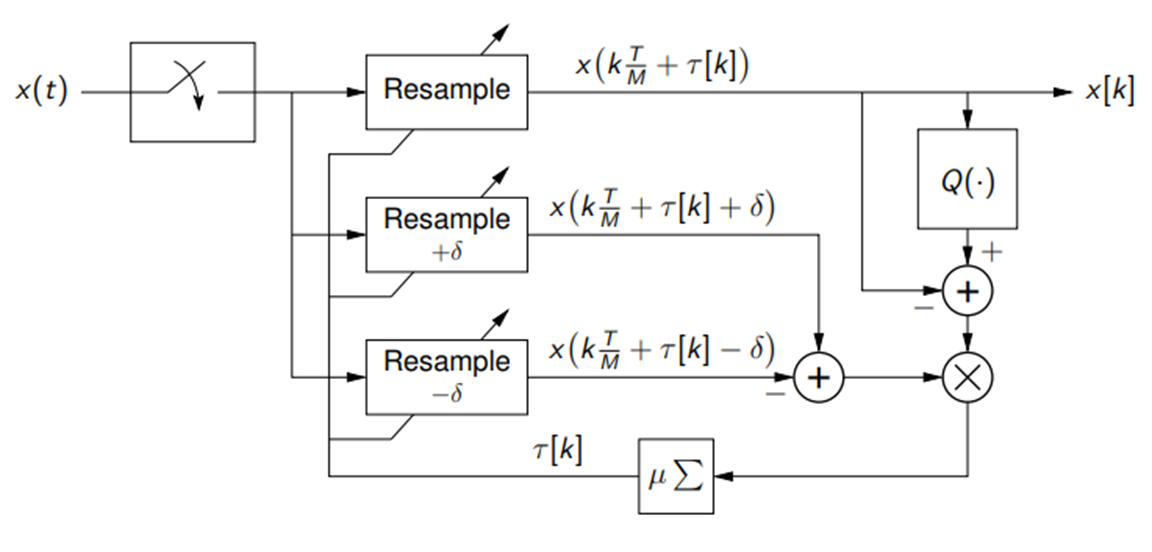

% Initialize parameters
l=srrc_length;                                                        
x_down=zeros(1,N);                              % down smapled signal x_down 

%algorithm parameters
tnow=l*M+1; tau=0; 
tausave=zeros(1,N); tausave(1)=tau; i=0;                            
mu=0.1;                                                     %stepsize
delta=0.1;                                                  % time for derivative

while tnow<N-l*M                                            % run iteration
  i=i+1;
  x_down(i)=interpsinc(x_BB,tnow+tau,l);                                   % interpolated value at tnow+tau
  x_deltap=interpsinc(x_BB,tnow+tau+delta,l);                          % get value to the right
  x_deltam=interpsinc(x_BB,tnow+tau-delta,l);                          % get value to the left
  dx=x_deltap-x_deltam;                                             % calculate numerical derivative
  qx=quantalph(x_down(i),[-3,-1,1,3]);                                  % quantize xs to nearest 4-PAM symbol
  tau=tau+mu*dx*(qx-x_down(i));                                         % alg update: DD
  tnow=tnow+M; tausave(i)=tau;                                      % save for plotting
end

x_down=2.7.*x_down(1:i-2);         % cut at the end of data points and upscale amplitude to fit 4-pam ranges

N= length(x_down);                  % redefine message length

Plot results

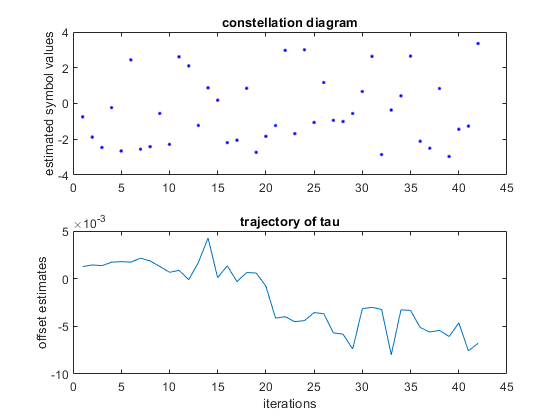

figure(3)
subplot(2,1,1), plot(x_down,'b.')                                % plot constellation diagram
title('constellation diagram');
ylabel('estimated symbol values')
subplot(2,1,2), plot(tausave(1:i-2))                                % plot trajectory of tau
title('trajectory of tau');
ylabel('offset estimates'), xlabel('iterations')

#### 7. matched filtering and header/ frames extractionn 

Apply correlation to the signal and preamble to specifiy positions of header (at peaks)

preamble1 = letters2pam(preamble);                                 

Error using dec2base (line 22)
First argument must be an array of integers, 0 <= D <= flintmax.

Error in letters2pam (line 8)
  f(4*k+1:4*k+4)=2*(dec2base(double(str(k+1)),4,4))-99;

corrSignal = filter(flip(preamble1), 1, x_down);                     % correlate preamble with the signal
mean = sum(corrSignal)/length(corrSignal);                       
meanVector=mean*ones(1,length(corrSignal));

corrSignalSqrd = (corrSignal-meanVector).^2;                     
                                                        

% Plot resultsfigure(4)
subplot(2,1,1); plot(1:length(corrSignal), corrSignal);             % plot correlation results 
title('correlation of preamble with the signal');
xlabel('signal data points')
subplot(2,1,2); plot(1:length(corrSignalSqrd), corrSignalSqrd);     % plot squared difference results
title('squared difference of correlation');
xlabel('signal data points')

specify peaks in the correlated squared signal

[peak, peakIdx]=max(corrSignalSqrd);                                       % get maximum value peak 
pos=0;

peaks=zeros(1, peakIdx);                                           % initiate peaks position vector                                 
count=0;

for k=1:length(corrSignalSqrd)
    if corrSignalSqrd(k) >=peak/1.5                                 % check if the peak is over 2/3 of the max value
        if k-pos > 100                                            
            peaks(count+1)=k;
            peak=corrSignalSqrd(k);                                 % register the peak                                              
            count=count+1;
        end
    end
end                            
peaks=peaks(1:count+1);                                             % cut the excessive zeros out of peak vector
peaks(count+1)=N;                                           % define the end of the signal


extract message frames and header

Header

header=x_down(peaks(1)+1-length(preamble):peaks(1));                      

Message

%extract message frame by frame
lenMsg=length(x_down(peaks(1)+1:end))-length(preamble)*(length(peaks)-1);
x_message=zeros(1,lenMsg);                                            % initialize message array
msgIdx=1;

for k=1:length(peaks)-1                                             % iterate through peaks
    frame=x_down(peaks(k)+1:peaks(k+1)-length(header));  
    x_message(msgIdx:msgIdx+length(frame)-1)=frame;
    msgIdx = msgIdx+length(frame);
end


#### 8. Equilizer

Pass header through LMS equilizer and message through DD equilizer.

Equilizer filter is the combination of both equilizers. That seems to give best results

nTaps=7;                                                                % set the taps
muLMS=.005; delta=4;                                                % LMS stepsize and delay delta
muDD=.006;                                                          % DD stepsize
f=zeros(nTaps,1);  


for i=nTaps+1:length(header)                                             % iterate
   rr=header(i:-1:i-nTaps+1)';                                           % vector of received signal
   e=preamble(i-delta)-rr'*f;                                   % calculate error
   f=f+muLMS*e*rr;                                              % update equalizer coefficients
end
  
 
for i=nTaps+1:length(x_message)                                             % iterate
   rr=x_message(i:-1:i-nTaps+1)';                                           % vector of received signal
   e=quantalph(f'*rr,[-3,-1,1,3])'-f'*rr;                       % calculate error
   f=f+muDD*e*rr;                                               % update equalizer coefficients
end
 

Apply equilizer filter

x_message_equ=filter(f,1,x_message);                            % filter the frame with trained filter

plot soft decisions after equilization

figure(5)
plot(x_message_equ,'b.'); 
title('sof decisions'); 

#### 9. Quantization

mprime=quantalph(x_message_equ,[-3,-1,1,3])';       

#### **10. PAM ecoder**

reconstructed_message=pam2letters(mprime);                        

## Display Message

disp(reconstructed_message);

## save results

To save results to local directory /results/ please run **saveResults** in the command lind.